% Problem 2 %
% ========= %
N_d = 10^15; % Donor doping concentration
N_a = 10^17; % Acceptor doping concentration
E_v = 0; % Taking valence band at zero for reference
E_c = 1.12; % Conduction band energy level of Si with refernce to valence band
E_d = E_c - 0.045; % Phosphorus ionization energy, E_ion = 0.045 eV
E_a = E_v + 0.045; % Boron ionization energy, E_ion = 0.045 eV
N_v = 1.04 * 10^19; % Density of states in valence band
N_c = 2.8 * 10^19; % Density of states in conduction band
E_mid = 0.5*(E_c + E_v); % Midgap of energy band

if N_d > N_a
    E_f = E_d;
elseif N_a > N_d
    E_f = E_a;
else
    E_f = E_mid;
end

for i = 1:1000

    N_d_plus = N_d/(1+2*exp((E_f-E_d)/0.0258));
    N_a_minus = N_a/(1+4*exp((E_a-E_f)/0.0258));
    n = N_c*exp((E_f-E_c)/0.0258);
    p = N_v*exp((E_v-E_f)/0.0258);

    f = N_d_plus - N_a_minus + p - n;

    f_1 = -(N_d_plus*(1+0.5*exp((E_d-E_f)/0.0258))^(-1)*(0.0258)^(-1))-(N_a_minus*(1+0.25*exp((E_f-E_a)/0.0258))^(-1)*(0.0258)^(-1))-(n*(0.0258)^(-1))-(p*(0.0258)^(-1));
    E_f = E_f - (f/f_1);
    
end

fprintf("The Fermi Energy level is %f eV above valnece band energy level.",E_f);

The Fermi Energy level is 0.124484 eV above valnece band energy level.

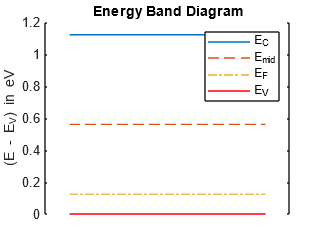


% Energy Band Diagram
X = 1:9;
E_C = zeros(1,9);
E_V = zeros(1,9);
E_MID = zeros(1,9);
E_F = zeros(1,9);

for i = 1:9
    E_C(1,i) = E_c;
    E_V(1,i) = E_v;
    E_MID(1,i) = E_mid;
    E_F(1,i) = E_f;
end

plot(X,E_C,'Displayname','E_C');
hold on
plot(X,E_MID,"--",'Displayname','E_{mid}');
plot(X,E_F,"-.",'Displayname','E_F');
E_1 = plot(X,E_V,"r",'Displayname','E_V');
h = gca;
h.XAxis.Visible = 'off';
ylabel("(E - E_V) in eV")
title("Energy Band Diagram")
legend